y'' + 3y' + 2y = e(-t), y(0)=4, y'(0)=5

syms s t Y

우변 라플라스

f = exp(-t);
F = laplace(f,t,s);

y'(t) : Y1 = sY - y(0)

Y1 = s*Y - 4;

y''(t) : Y2 = sY1 - y'(0)

Y2 = s*Y1 - 5;

라플라스 (desolve아님)

Sol = solve(Y2 + 3*Y1 + 2*Y - F, Y)

$$Sol = \frac{4\,s+\frac{1}{s+1}+17}{s^{2}+3\,s+2}$$

역라플라스

sol = ilaplace(Sol, s, t)

$$sol = 12\,{\mathrm{e}}^{-t}-8\,{\mathrm{e}}^{-2\,t}+t\,{\mathrm{e}}^{-t}$$

# --------------------------------------------------

y'' + 3y' + 2y = f(t), y(0)=2, y'(0)=3

f(t) = 1, t<3

f(t) = t-2, 3<t<6

f(t) = 2, 6<t

clear clc
syms s t Y

heaviside = 계단함수

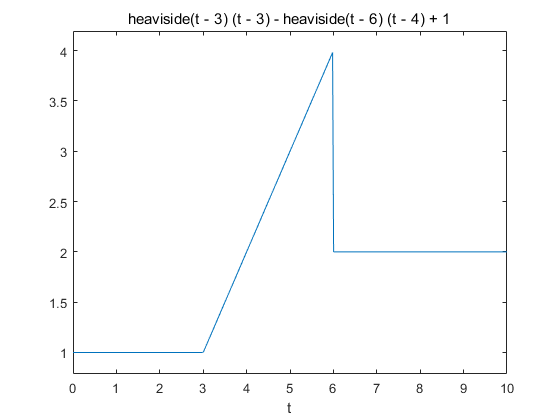

f = 1 + ((t-2)-1) * heaviside(t-3) + (2-(t-2))*heaviside(t-6);
figure;
ezplot(f, [0, 10])

앞선 과정과 같음

F = laplace(f,t,s);
Y1 = s*Y - 2;
Y2 = s*Y1 - 3;
Sol = solve(Y2 + 3*Y1 + 2*Y - F, Y)

$$Sol = \frac{2\,s+\frac{{\mathrm{e}}^{-3\,s}}{s^{2}}+\frac{1}{s}-\frac{{\mathrm{e}}^{-6\,s}\,\left(2\,s+1\right)}{s^{2}}+9}{s^{2}+3\,s+2}$$

sol = ilaplace(Sol, s, t)

$$sol = \begin{array}{l} 6\,{\mathrm{e}}^{-t}-\frac{9\,{\mathrm{e}}^{-2\,t}}{2}+\mathrm{heaviside}\left(t-3\right)\,\left(\frac{t}{2}+{\mathrm{e}}^{3-t}-\frac{{\mathrm{e}}^{6-2\,t}}{4}-\frac{9}{4}\right)-\mathrm{heaviside}\left(t-6\right)\,\left(\frac{t}{2}+{\mathrm{e}}^{6-t}-\frac{\sigma_{1}}{4}-\frac{15}{4}\right)-2\,\mathrm{heaviside}\left(t-6\right)\,\left(\frac{\sigma_{1}}{2}-{\mathrm{e}}^{6-t}+\frac{1}{2}\right)+\frac{1}{2}\\ \mathrm{where}\\ \sigma_{1}={\mathrm{e}}^{12-2\,t} \end{array}$$

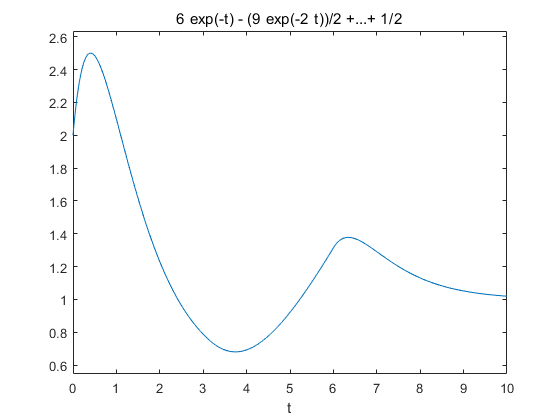

figure;
ezplot(sol, [0, 10])

# ----------------------------------------------------------------

y'' + 2y' + 10y = 1 + 5delta(t-5), y(0)=1, y'(0)=2

sol1) 라플라스

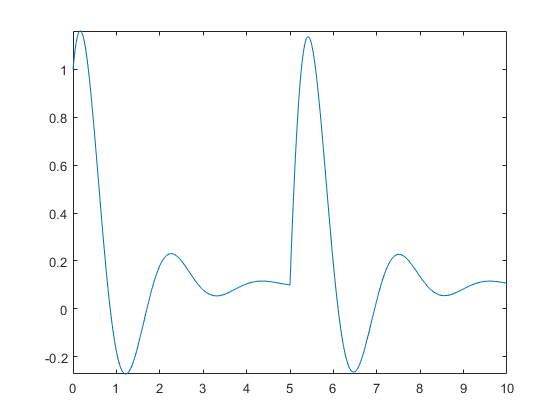

clear clc
syms s t Y y(t)

f = 1 + 5*dirac(t-5);
F = laplace(f, t, s);

Y1 = s*Y - 1;
Y2 = s*Y1 - 2;
Sol = solve(Y2 + 2*Y1 + 10*Y - F, Y);
sol = ilaplace(Sol, s, t);
figure; fplot(sol, [0, 10])

sol2) 시간영역 미방

clear clc
eq1 = diff(y, t, 2) + 2*diff(y, t, 1) + 10*y == 1 + 5*dirac(t-5);
Dy = diff(y,t); 
conds1 = [y(0)==1, Dy(0)==2];
sol2 = dsolve(eq1, conds1);
figure; fplot(sol2, [0, 10]);